# EE4530 Applied Convex Optimization mini-Project - SVM

## Clear all

clear all;
clc;
close all;

## 1. Data Load

load("linear_svm.mat");

### Data Exploration

Take a look at the distribution of the data

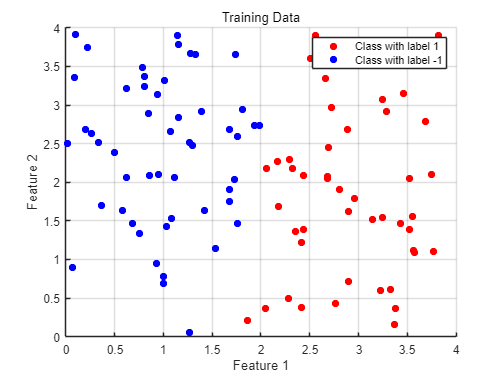

% plot the training data
figure;

% plot data with label = 1
scatter(X_train(labels_train == 1, 1), X_train(labels_train == 1, 2), 'ro', 'filled');
hold on;

% plot data with label = -1
scatter(X_train(labels_train == -1, 1), X_train(labels_train == -1, 2), 'bo', 'filled');

title('Training Data');
xlabel('Feature 1');
ylabel('Feature 2');
legend('Class with label 1', 'Class with label -1');

% display
grid on;
% axis padded;
hold off;

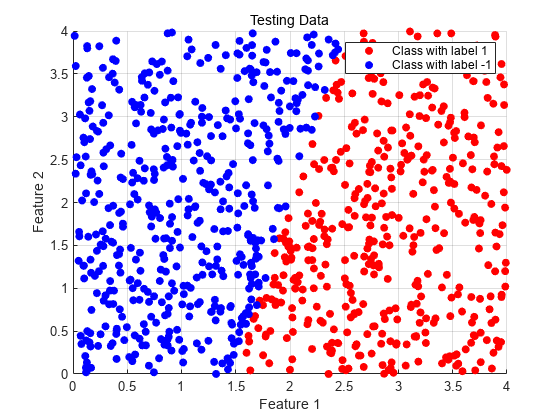

% plot the testing data
figure;

% plot data with label=1
scatter(X_test(labels_test == 1, 1), X_test(labels_test == 1, 2), 'ro', 'filled');
hold on;

% plot data with label=-1
scatter(X_test(labels_test == -1, 1), X_test(labels_test == -1, 2), 'bo', 'filled');

title('Testing Data');
xlabel('Feature 1');
ylabel('Feature 2');
legend('Class with label 1', 'Class with label -1');

% display
grid on;
hold off;

## 1.Task 1

We choose hard-margin SVM as the optimization problem in our project. The objective of hard-margin SVM and the constraint are shown below. 


$$\min_{\vec{w}} f(\vec{w})=\frac{||\vec{w}||^2}{2} \\
\text{s.t.}  \ g_i(\vec{w}, b) = y_i \cdot(\vec{w}\cdot \vec{x_i} + b) \geq 1

$$


[N_train, n] = size(X_train);
[N_test, n] = size(X_test);


## Using CVX to Solve the Problem


tic;
% CVX
cvx_begin
    variables w(n) b delta(N_train);
    % Objective
    minimize(0.5 * w' * w);

    % Constraints
    subject to
        for i = 1:N_train
            labels_train(i) * (X_train(i, :) * w + b) >= 1
        end
cvx_end

 
Calling SDPT3 4.0: 104 variables, 4 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  4
 dim. of socp   var  =  4,   num. of socp blk  =  1
 dim. of linear var  = 100
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|9.7e+02|2.4e+01|5.0e+04|-2.000000e+03  0.000000e+00| 0:0:00| chol  1  1 
 1|0.410|0.416|5.7e+02|1.4e+01|4.0e+04|-1.397413e+03 -7.987107e+01| 0:0:00| chol  1  1 
 2|0.300|0.326|4.0e+02|9.3e+00|3.5e+04|-9.280953e+02 -2.648473e+02| 0:0:00| chol  1  1 
 3|0.202|0.255|3.2e+02|7.0e+00|3.3e+

time_cvx = toc

time_cvx = 1.1493

y_pre = svm_predict(w, b, X_test);
cvx_test_accuracy = svm_report(labels_test, y_pre);
fprintf("Optimal w: (%f, %f)'\nOptimal b: %f\nRunning time: %f\nTesting Accuracy: %f", w(1), w(2), b, time_cvx, cvx_test_accuracy);

Optimal w: (11.255635, -1.973901)'
Optimal b: -17.888523
Running time: 1.149346
Testing Accuracy: 0.976667

## 2. Task 2

We mainly use projected gradient descent algorithm to solve the dual problem. 


$$\[
L(\mathbf{w}, b, \mathbf{\lambda}) = \frac{1}{2} \|\mathbf{w}\|^2 
+ \sum_{i=1}^m \lambda_i \Bigl[1 - y_i \bigl(\mathbf{w} \cdot \mathbf{x}_i + b\bigr)\Bigr] 
\quad\text{subject to}\quad \lambda_i \geq 0,\; i = 1, \ldots, m.
\]
$$


% data preprocessing
X_train_normalized = normalize(normalize(X_train), "range");
X_test_normalized = normalize(normalize(X_test), "range");

% hyperparameters
lambda = 0.01;
t = 0.001;
num_iters = 500;

## Dual + PGD

tic;
[w_dual, b_dual, acc_dual] = svm_dual_gd(X_train_normalized, labels_train, X_test_normalized, labels_test, t, num_iters);
time_dual_gd = toc;
y_pre = svm_predict(w_dual, b_dual, X_test_normalized);
test_dual_accuracy = svm_report(labels_test, y_pre);
fprintf("Optimal w: (%f, %f)'\nOptimal b: %f\nRunning time: %f\nTesting Accuracy: %f", w_dual(1), w_dual(2), b_dual, time_dual_gd, test_dual_accuracy);

Optimal w: (0.840103, -0.188161)'
Optimal b: -0.347670
Running time: 0.031310
Testing Accuracy: 0.966667

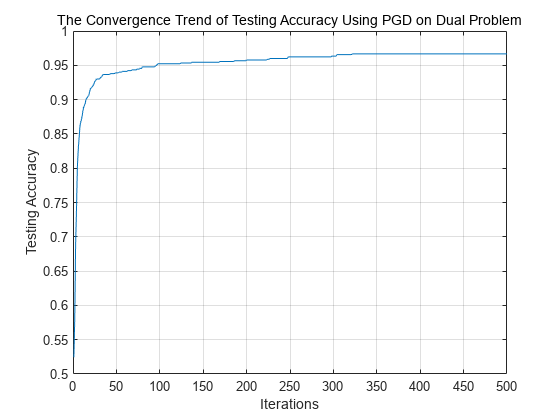

plot(acc_dual);
title("The Convergence Trend of Testing Accuracy Using PGD on Dual Problem");
xlabel("Iterations");
ylabel("Testing Accuracy");
grid on;

## Hinge Loss + GD

tic;
[w_gd, b_gd, gd_acc] = svm_gd(X_train_normalized, labels_train, X_test_normalized, labels_test, lambda, t, num_iters);
time_gd = toc;
y_pre = svm_predict(w_gd, b_gd, X_test_normalized);
test_gd_accuracy = svm_report(labels_test, y_pre);
fprintf("Optimal w: (%f, %f)'\nOptimal b: %f\nRunning time: %f\nTesting Accuracy: %f", w_gd(1), w_gd(2), b_gd, time_gd, test_gd_accuracy);

Optimal w: (3.639986, -0.940936)'
Optimal b: -1.377320
Running time: 0.018335
Testing Accuracy: 0.987778

## Comparison

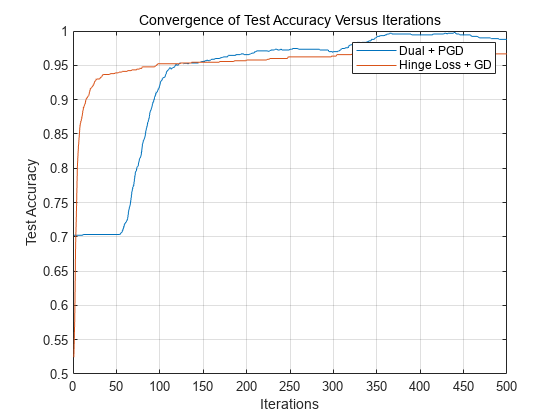

plot(gd_acc);
hold on;
plot(acc_dual);
grid on;
title('Convergence of Test Accuracy Versus Iterations');
xlabel("Iterations");
ylabel("Test Accuracy");
legend('Dual + PGD', 'Hinge Loss + GD');